## IMPATTO DEGLI ERRORI DI STIMA SUL PORTAFOGLIO OTTIMO IN MEDIA-VARIANZA

In questo script ipotizziamo due asset con rendimenti congiuntamente normali. Immaginiamo di conoscere i parametri veri, oltre a un coefficiente di avversione al rischio $\lambda =3$

trueMu = [0.07; 0.05];
trueVols = [0.20; 0.15]; % deviazione standard del rendimento
trueRho = 0.7;
% trucco per ottenere matrice di covarianza da matrice correlazione
trueSigma = [1 trueRho; trueRho 1].*(trueVols * trueVols');
lambda = 3;

Sulla base dei parametri veri, costruiamo un portafoglio ottimo. A questo scopo, introduciamo una funzione (quadfolio, riportata alla fine dello script) per ricavarne i pesi, il valore atteso e la volatilità. Non imponiamo vincoli di non vendita allo scoperto, quindi abbiamo la soluzione analitica. 

[truewp,mup,sigmap] = QuadFolio(trueMu, trueSigma, lambda);
truew1 = truewp(1)

truew1 = 0.3984

Questo è il peso dell'asset 1 nel portafoglio ottimo "vero". 

NB:  Usiamo la funzione quadfolio, ma possiamo anche verificare usando la funzione quadprog:

options = optimoptions('quadprog','Display','none');
x = quadprog(lambda*trueSigma,-trueMu,[],[],ones(1,2),1,[],[],[],options);
x(1)

ans = 0.3984

La funzione quadprog non sfrutta la soluzione analitica, ma ci permetterebbe di risolvere il problema in presenza di vincoli lineari sulla composizione del portafoglio, compreso il vincolo che proibisce vendite allo scoperto.

Ora imaginiamo di osservare numSample=300 rendimenti e di stimare rendimenti attesi e covarianze, ottimizzando il portafoglio con la formula analitica. Ripetiamo l'esperimento numRepl=1000 volte.

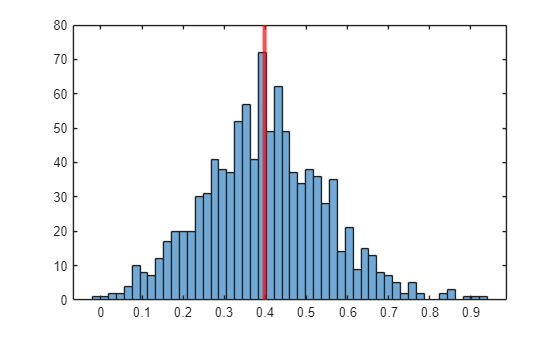

numRepl = 1000;
numSample = 300;
rng('default'); % ripetibilità
% vettore per i pesi dell'asset 1 nel portafoglio ottimo stimato
w1 = zeros(numRepl,1);
for k=1:numRepl
   retScenarios = mvnrnd(trueMu,trueSigma,numSample);
   hatMu = mean(retScenarios);
   hatSigma = cov(retScenarios);
   [wp,mup,sigmap] = QuadFolio(hatMu, hatSigma, lambda);
   w1(k) = wp(1);
end
histogram(w1,50);
xline(truew1,'r','LineWidth',3);

Si nota l'estrema variabilità del peso nel portafoglio (la barra in rosso mostra il valore ottimo "vero"). Provate a vedere di quanto migliora la soluzione se stimiamo sulla base di 3000 osservazioni. Se stiamo parlando di rendimenti annuali, temo che non avremo a disposizione 3000 anni di prezzi.

La funzione quadfolio è definita come segue (per le formule, vedete le slide del corso):

function [wp,mup,sigmap] = QuadFolio(expRet, covMat, lambda)
n = length(expRet);
iVet = ones(n,1);
mu = expRet(:);
invSigma = inv(covMat);
charII = iVet' * invSigma * iVet;
charIM = iVet' * invSigma * mu;
wp = invSigma*iVet/charII + ...
    1/lambda * (charII*invSigma*mu - charIM*invSigma*iVet)/charII;
mup = wp'*mu;
sigmap = sqrt(wp' * covMat * wp);
end